# Maintain Glucose in Type-I Diabetic

This assignment is to design an artificial pancreas for a Type-I diabetic. A Type-I diabetic has no insulin production in the pancreas. Insulin production in the pancreas is used to regulate a person’s blood glucose level. When that natural production does not exist, glucose is monitored at regular intervals and insulin is injected as needed. With the recent development of continuous blood glucose monitors and the established success of continuous insulin pumps, it is now possible to create a controller that automatically regulates blood glucose by adjusting the injection rate of insulin.

This development is needed because of the increased rates of diabetes within the U.S. as tracked by the Center for Disease Control (CDC). The incidence of diabetes mellitus is predicted to be 33% by 2050 if current trends continue. Currently 8-9% or 26 million Americans are affected by this condition with yearly direct medical costs of $116 billion and even higher indirect costs.

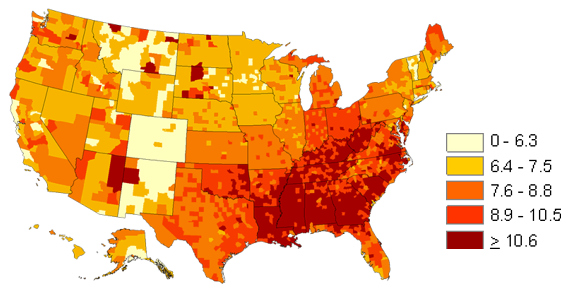

The set point for blood glucose concentration is expected to remain within a specified range that is typical of a healthy individual. A typical range for a healthy individual is between 64 and 104 mg/dL (3.6 and 5.8 mmol/L) with a target of 80 mg/dL. Blood glucose values that are out of range are undesirable but values that are too low are much more serious and can lead to hospitalization or death if left untreated.

The insulin pump is a continuous injection into the person’s body. It can deliver flow rates between 0.0 and 10.0 μU/min with a typical base value of 3.0 μU/min. The controller must restrict values of the flow to this range during the controller testing although it is typical with these devices to allow small one-time injections when needed.

## Determine FOPDT Model

viewSolution(true)

% Steady State Initial Conditions for the States
y0 = [76.22, 33.33, 33.33,16.67,16.67,250.0];

% Steady State Initial Condition for the Control
u_ss = 3.0; % mU/min

% Steady State for the Disturbance
d_ss = 1000.0; % mmol/L-min

% Final Time (hr)
tf = 24;      % simulate for 24 hours
ns = tf*6+1;  % sample time = 10 min

% Time Interval (min)
t = linspace(0,tf,ns);

% Store results for plotting
G = ones(1,length(t)) * y0(1);
X = ones(1,length(t)) * y0(2);
I = ones(1,length(t)) * y0(3);
u = ones(1,length(t)) * u_ss;
d = ones(1,length(t)) * d_ss;

% Step response for insulin
u(10:end) = 2.8;

% Add meal disturbances
meals = [1259,1451,1632,1632,1468,1314,1240,1187,1139,1116,...
          1099,1085,1077,1071,1066,1061,1057,1053,1046,1040,...
          1034,1025,1018,1010,1000,993,985,976,970,964,958,...
          954,952,950,950,951,1214,1410,1556,1603,1445,1331,...
          1226,1173,1136,1104,1088,1078,1070,1066,1063,1061,...
          1059,1056,1052,1048,1044,1037,1030,1024,1014,100

**The function **`diabetic`** is provided for your conventience below.** Perform the necessary open loop dynamic modeling studies to determine a first order plus dead time (FOPDT) model which describes process operation near the design operation conditions (use the first 7 hours of data without meal disturbances). Report values of $K_p,\tau_p$ and $\theta_p$.

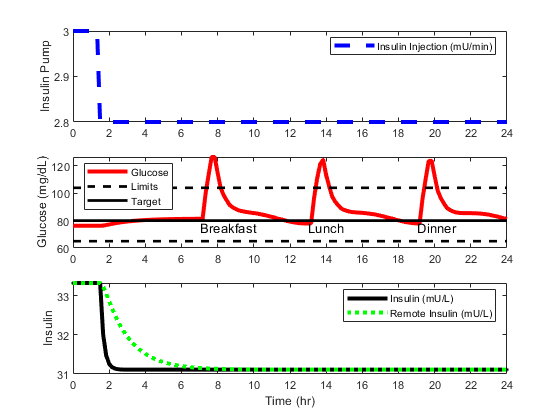

% Steady State Initial Conditions for the States
y0 = [76.22, 33.33, 33.33,16.67,16.67,250.0];

% Steady State Initial Condition for the Control
u_ss = 3.0; % mU/min

% Steady State for the Disturbance
d_ss = 1000.0; % mmol/L-min

% Final Time (hr)
tf = 24      ;% simulate for 24 hours
ns = tf*6+1  ;% sample time = 10 min

% Time Interval (min)
t = linspace(0,tf,ns);

% Store results for plotting
G = ones(length(t)) * y0(1);
X = ones(length(t)) * y0(2);
I = ones(length(t)) * y0(3);
u = ones(length(t)) * u_ss;
d = ones(length(t)) * d_ss;
u(10:end) = 2.8;

%Add meal disturbances
meals = [1259,1451,1632,1632,1468,1314,1240,1187,1139,1116,...
	              1099,1085,1077,1071,1066,1061,1057,1053,1046,1040,...
	              1034,1025,1018,1010,1000,993,985,976,970,964,958,...
	              954,952,950,950,951,1214,1410,1556,1603,1445,1331,...
	              1226,1173,1136,1104,1088,1078,1070,1066,1063,1061,...
	              1059,1056,1052,1048,1044,1037,1030,1024,1014,1007,...
	              999,989,982,975,967,962,957,953,951,950,1210,1403,...
	              1588,1593,1434,1287,1212,1159,1112,1090,1075,1064,...
	              1059,1057,1056,1056,1056,1055,1054,1052,1049,1045,...
	              1041,1033,1027,1020,1011,1003,996,986];
for i = 1:length(meals)
    d(i+43) = meals(i);
end 

for i = 1:length(u)-1

    jz = @(t,y) diabetic(t, y,u(i),d(i));
    ts = [t(i) t(i+1)];
    [~,y] = ode45(jz,ts,y0);
    G(i+1) = y(end,1);
    X(i+1) = y(end,2);
    I(i+1) = y(end,3);
    y0 = y(end,:);
end
% Plot results
ticks = linspace(0,24,13); 
subplot(3,1,1); 
plot(t(1:i+1),u(1:i+1),'--b','LineWidth', 3); 
ylabel('Insulin Pump'); 
legend({'Insulin Injection (mU/min)'}); 
xlim([0,24]); 
xticks(ticks); 

subplot(3,1,2); 
h1 = plot(t(1:i+1),G(1:i+1),'-r','LineWidth', 3); hold on 
h2 = plot([0,24],[104,104],'--k','LineWidth', 2); 
h3 = plot([0,24],[80,80],'-k','LineWidth', 2); 
plot([0,24],[65,65],'--k','LineWidth', 2); hold off 
ylabel('Glucose (mg/dL)'); 
legend([h1 h2 h3],{'Glucose', 'Limits', 'Target'},'Location', 'northwest'); 
xlim([0,24]); 
xticks(ticks); 
text(7, 75, 'Breakfast'); 
text(13, 75, 'Lunch'); 
text(19, 75, 'Dinner'); 

subplot(3,1,3); 
plot(t(1:i+1),I(1:i+1),'k.-','LineWidth', 3,'DisplayName','Insulin (mU/L)'); hold on 
plot(t(1:i+1),X(1:i+1),'g:','LineWidth', 3,'DisplayName','Remote Insulin (mU/L)'); hold off 
ylabel('Insulin'); 
xlabel('Time (hr)'); 
xlim([0,24]); 
legend(); 
xticks(ticks); 

## Determine Initial PID Tuning

viewSolution2(false)

Using $K_c,\tau_I$ and $\tau_D$, compute the tuning parameters for a PID controller from the IMC tuning correlation. Report the tuning parameters.

### Fit FOPDT Model

### Obtain PID Tuning Parameters (IMC Controller)

## Implement PID Controller

viewSolution3(false)

Using $K_c,\tau_I$ and $\tau_D$, implement a PID with anti-reset windup. Test the disturbance rejection capability of this controller by plotting the response of the process to meal disturbances. Comment on how the nonlinear behavior of this process impacts our observed disturbance rejection performance. Turn in a plot for the default IMC parameters, along with comments.

## Tune PID Controller

viewSolution4(false)

Determine a *best* tuning by adjusting $K_c,\tau_I$ and $\tau_D$ until the controller response is improved (use quantitative measures like time outside the upper and lower limits). Plot the best disturbance rejection response. Turn in final plot and values of tuning parameters.

## Generate Tuning Sensitivity Guide

viewSolution5(false)

Run six tuning cases and plot the response of each compared to the tuned controller. The first two cases should use the best τIτI and τDτD but should use double and then half of the best $K_c$. The next two cases should use the best $K_c$ and $\tau_D$, but should use double and then half of the best $\tau_I$. The final two cases should use the best $K_c$ and $\tau_I$, but should use double and then half of the best $\tau_D$. Comment on how the tuning parameters interact and impact controller performance. Turn in plots along with comments. Put all trends for each parameter on one plot for the sake of direct comparison.

## Diabetic Model

function dydt = diabetic(~,y,ui,d)
    % Inputs (2)
    % U = Insulin infusion rate (mU/min)
    % D = Meal disturbance (mmol/L-min)

    % Expanded Bergman Minimal model to include meals and insulin
    % Parameters for an insulin dependent type-I diabetic

    % States (6):
    % In non-diabetic patients, the body maintains the blood glucose
    %  level at a range between about 3.6 and 5.8 mmol/L (64.8 and
    %  104.4 mg/dL with 1:18 conversion between mmol/L and mg/dL)
    g = y(1);                % blood glucose (mg/dL)
    x = y(2);                % remote insulin (micro-u/ml)
    i = y(3);                % insulin (micro-u/ml)
    q1 = y(4);
    q2 = y(5);
    g_gut = y(6);            % gut blood glucose (mg/dl)

    % Parameters:
    gb    = 291.0;           % Basal Blood Glucose (mg/dL)
    p1    = 3.17e-2;         % 1/min
    p2    = 1.23e-2;         % 1/min
    si    = 2.9e-2;          % 1/min * (mL/micro-U)
    ke    = 9.0e-2;          % 1/min
    kabs  = 1.2e-2;          % 1/min
    kemp  = 1.8e-1;          % 1/min
    f     = 8.00e-1;         % L
    vg    = 12.0;            % L

    % Compute ydot:
    dydt = zeros(1,6);
    dydt(1) = -p1*(g-gb) - si*x*g + f*kabs/vg * g_gut + f/vg * d;
    dydt(2) =  p2*(i-x); % remote insulin compartment dynamics
    dydt(3) = -ke*i + ui; % insulin dynamics
    dydt(4) = ui - kemp * q1;
    dydt(5) = -kemp*(q2-q1);
    dydt(6) = kemp*q2 - kabs*g_gut;

    % convert from minutes to hours
    dydt = dydt*60;
    dydt = dydt.';
end

## Solutions

function viewSolution(view)
if view
	disp("% Steady State Initial Conditions for the States" + newline + ...
	     "y0 = [76.22, 33.33, 33.33,16.67,16.67,250.0];" + newline + ...
	     "" + newline + ...
	     "% Steady State Initial Condition for the Control" + newline + ...
	     "u_ss = 3.0; % mU/min" + newline + ...
	     "" + newline + ...
	     "% Steady State for the Disturbance" + newline + ...
	     "d_ss = 1000.0; % mmol/L-min" + newline + ...
	     "" + newline + ...
	     "% Final Time (hr)" + newline + ...
	     "tf = 24;      % simulate for 24 hours" + newline + ...
	     "ns = tf*6+1;  % sample time = 10 min" + newline + ...
	     "" + newline + ...
	     "% Time Interval (min)" + newline + ...
	     "t = linspace(0,tf,ns);" + newline + ...
	     "" + newline + ...
	     "% Store results for plotting" + newline + ...
	     "G = ones(1,length(t)) * y0(1);" + newline + ...
	     "X = ones(1,length(t)) * y0(2);" + newline + ...
	     "I = ones(1,length(t)) * y0(3);" + newline + ...
	     "u = ones(1,length(t)) * u_ss;" + newline + ...
	     "d = ones(1,length(t)) * d_ss;" + newline + ...
	     "" + newline + ...
	     "% Step response for insulin" + newline + ...
	     "u(10:end) = 2.8;" + newline + ...
	     "" + newline + ...
	     "% Add meal disturbances" + newline + ...
	     "meals = [1259,1451,1632,1632,1468,1314,1240,1187,1139,1116,..." + newline + ...
	     "          1099,1085,1077,1071,1066,1061,1057,1053,1046,1040,..." + newline + ...
	     "          1034,1025,1018,1010,1000,993,985,976,970,964,958,..." + newline + ...
	     "          954,952,950,950,951,1214,1410,1556,1603,1445,1331,..." + newline + ...
	     "          1226,1173,1136,1104,1088,1078,1070,1066,1063,1061,..." + newline + ...
	     "          1059,1056,1052,1048,1044,1037,1030,1024,1014,1007,..." + newline + ...
	     "          999,989,982,975,967,962,957,953,951,950,1210,1403,..." + newline + ...
	     "          1588,1593,1434,1287,1212,1159,1112,1090,1075,1064,..." + newline + ...
	     "          1059,1057,1056,1056,1056,1055,1054,1052,1049,1045,..." + newline + ...
	     "          1041,1033,1027,1020,1011,1003,996,986];" + newline + ...
	     "for i=1:length(meals)" + newline + ...
	     "    d(i+43) = meals(i);" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "% Create plot" + newline + ...
	     "clf" + newline + ...
	     "" + newline + ...
	     "% Simulate Type-I Diabetic Blood Glucose" + newline + ...
	     "for i = 1:length(t)-1" + newline + ...
	     "    ts = [t(i),t(i+1)];" + newline + ...
	     "    [~,y] = ode45(@(t,y) diabetic(t,y,u(i+1),d(i+1)),ts,y0);" + newline + ...
	     "    G(i+1) = y(end,1);" + newline + ...
	     "    X(i+1) = y(end,2);" + newline + ...
	     "    I(i+1) = y(end,3);" + newline + ...
	     "    y0 = y(end,:);" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "% plot results" + newline + ...
	     "ticks = linspace(0,24,13);" + newline + ...
	     "subplot(3,1,1);" + newline + ...
	     "plot(t(1:i+1),u(1:i+1),'--b','LineWidth', 3);" + newline + ...
	     "ylabel('Insulin Pump');" + newline + ...
	     "legend({'Insulin Injection (mU/min)'});" + newline + ...
	     "xlim([0,24]);" + newline + ...
	     "xticks(ticks);" + newline + ...
	     "" + newline + ...
	     "subplot(3,1,2);" + newline + ...
	     "h1 = plot(t(1:i+1),G(1:i+1),'-r','LineWidth', 3); hold on" + newline + ...
	     "h2 = plot([0,24],[104,104],'--k','LineWidth', 2);" + newline + ...
	     "h3 = plot([0,24],[80,80],'-k','LineWidth', 2);" + newline + ...
	     "plot([0,24],[65,65],'--k','LineWidth', 2); hold off" + newline + ...
	     "ylabel('Glucose (mg/dL)');" + newline + ...
	     "legend([h1 h2 h3],{'Glucose', 'Limits', 'Target'},'Location', 'northwest');" + newline + ...
	     "xlim([0,24]);" + newline + ...
	     "xticks(ticks);" + newline + ...
	     "text(7, 75, 'Breakfast');" + newline + ...
	     "text(13, 75, 'Lunch');" + newline + ...
	     "text(19, 75, 'Dinner');" + newline + ...
	     "" + newline + ...
	     "subplot(3,1,3);" + newline + ...
	     "plot(t(1:i+1),I(1:i+1),'k.-','LineWidth', 3,'DisplayName','Insulin (mU/L)'); hold on" + newline + ...
	     "plot(t(1:i+1),X(1:i+1),'g:','LineWidth', 3,'DisplayName','Remote Insulin (mU/L)'); hold off" + newline + ...
	     "ylabel('Insulin');" + newline + ...
	     "xlabel('Time (hr)');" + newline + ...
	     "xlim([0,24]);" + newline + ...
	     "legend();" + newline + ...
	     "xticks(ticks);" + newline + ...
	     "" + newline + ...
	     "% Construct results and save data file" + newline + ...
	     "% Column 1 = time" + newline + ...
	     "% Column 2 = insulin rate" + newline + ...
	     "% Column 3 = blood glucose" + newline + ...
	     "data = vertcat(vertcat(t,u),G).';" + newline + ...
	 "end")
end
end

function viewSolution2(view)
if view
	disp("% ---Fit FOPDT Model---" + newline + ...
	     "du = -1;   % micro L unsulin per minute" + newline + ...
	     "dy = 35;  % Change in mg per deciliter" + newline + ...
	     "Kp = dy/du;" + newline + ...
	     "thetap = 0;" + newline + ...
	     "taup = 2;  % rough time to get 63% of the way to the finish" + newline + ...
	     "" + newline + ...
	     "" + newline + ...
	     "% ---Obtain PID Tuning Parameters (IMC Controller)---" + newline + ...
	     "tauc = max(.1 * taup, .8 * thetap);  % agressive Tuning" + newline + ...
	     "Kc = (taup + .5 * thetap) / (Kp * (tauc + .5 *thetap));" + newline + ...
	     "tauI = taup + .5 * thetap;" + newline + ...
	     "tauD = taup * thetap / (2 * taup + thetap);" + newline + ...
	     "" + newline + ...
	     "% derivative filter" + newline + ...
	     "alpha = (tauc * tauI) / (taup * (tauc + thetap));" + newline + ...
	     "" + newline + ...
	     "fprintf('tauc: %.4f',tauc)" + newline + ...
	     "fprintf('Kc: %.4f',Kc)" + newline + ...
	     "fprintf('tauI: %.4f',tauI);" + newline + ...
	 "end")
end
end

function viewSolution3(view)
if view
	disp("% (2) Establish time and setpoint arrays" + newline + ...
	     "% Final Time (hr)" + newline + ...
	     "tf = 24;      % simulate for 24 hours" + newline + ...
	     "ns = tf*6+1;  % sample time = 10 min" + newline + ...
	     "" + newline + ...
	     "% Time Interval (min)" + newline + ...
	     "t = linspace(0,tf,ns);" + newline + ...
	     "sp = ones(1,length(t))*80;  % mmol / L" + newline + ...
	     "" + newline + ...
	     "% (3) establish constants and storage arrays" + newline + ...
	     "% Steady State Initial Conditions for the States" + newline + ...
	     "y0 = [76.22, 33.33, 33.33,16.67,16.67,250.0];  % G I X q1, q1, g_gut" + newline + ...
	     "" + newline + ...
	     "% Steady State Initial Condition for the Control" + newline + ...
	     "u_ss = 3.0; % mU/min" + newline + ...
	     "" + newline + ...
	     "% Steady State for the Disturbance" + newline + ...
	     "d_ss = 1000.0; % mmol/L-min" + newline + ...
	     "" + newline + ...
	     "% Arrays" + newline + ...
	     "%# Model arrays" + newline + ...
	     "G = ones(1,length(t)) * y0(1);  % Blood Glucose" + newline + ...
	     "X = ones(1,length(t)) * y0(2);  % Remote insulin" + newline + ...
	     "u = ones(1,length(t)) * u_ss;   % insulin in per minute" + newline + ...
	     "d = ones(1,length(t)) * d_ss;   % disturbance value" + newline + ...
	     "" + newline + ...
	     "% Add meal disturbances" + newline + ...
	     "meals = [1259,1451,1632,1632,1468,1314,1240,1187,1139,1116,..." + newline + ...
	     "          1099,1085,1077,1071,1066,1061,1057,1053,1046,1040,..." + newline + ...
	     "          1034,1025,1018,1010,1000,993,985,976,970,964,958,..." + newline + ...
	     "          954,952,950,950,951,1214,1410,1556,1603,1445,1331,..." + newline + ...
	     "          1226,1173,1136,1104,1088,1078,1070,1066,1063,1061,..." + newline + ...
	     "          1059,1056,1052,1048,1044,1037,1030,1024,1014,1007,..." + newline + ...
	     "          999,989,982,975,967,962,957,953,951,950,1210,1403,..." + newline + ...
	     "          1588,1593,1434,1287,1212,1159,1112,1090,1075,1064,..." + newline + ...
	     "          1059,1057,1056,1056,1056,1055,1054,1052,1049,1045,..." + newline + ...
	     "          1041,1033,1027,1020,1011,1003,996,986];" + newline + ...
	     "for i=1:length(meals)" + newline + ...
	     "    d(i+43) = meals(i);" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "%% Controller Arrays" + newline + ...
	     "% storage for recording values" + newline + ...
	     "% op = zeros(1,length(t));  # controller output -- insulin in per minute" + newline + ...
	     "% pv = zeros(1,length(t));  # process variable -- Blood Glucose" + newline + ...
	     "e = zeros(1,length(t));   % error" + newline + ...
	     "ie = zeros(1,length(t));  % integral of the error" + newline + ...
	     "dpv = zeros(1,length(t)); % derivative of the pv" + newline + ...
	     "P = zeros(1,length(t));   % proportional" + newline + ...
	     "I = zeros(1,length(t));   % integral" + newline + ...
	     "D = zeros(1,length(t));   % derivative" + newline + ...
	     "" + newline + ...
	     "% (4) Establish bounds for anti-reset windup for output variable" + newline + ...
	     "% Upper and Lower limits on OP" + newline + ...
	     "op_hi = 10.0;" + newline + ...
	     "op_lo = 0.0;" + newline + ...
	     "" + newline + ...
	     "% (6) loop through" + newline + ...
	     "for i=1:length(t)-1" + newline + ...
	     "    delta_t = t(i+1)-t(i);" + newline + ...
	     "    e(i) = sp(i) - G(i);" + newline + ...
	     "    if i >= 2  % calculate starting on second cycle" + newline + ...
	     "        dpv(i) = (G(i)-G(i-1))/delta_t;" + newline + ...
	     "        ie(i) = ie(i-1) + e(i) * delta_t;" + newline + ...
	     "    end" + newline + ...
	     "    P(i) = Kc * e(i);" + newline + ...
	     "    I(i) = Kc/tauI * ie(i);" + newline + ...
	     "    D(i) = - Kc * tauD * dpv(i);" + newline + ...
	     "    u(i) = u(1) + P(i) + I(i) + D(i);" + newline + ...
	     "    try" + newline + ...
	     "        du = u(i) - u(i-1);" + newline + ...
	     "        derivative_filter = -alpha * tauD * du/delta_t;" + newline + ...
	     "        u(i) = u(1) + P(i) + I(i) + D(i) + derivative_filter;" + newline + ...
	     "    catch" + newline + ...
	     "        " + newline + ...
	     "    end" + newline + ...
	     "    if u(i) > op_hi  % check upper limit" + newline + ...
	     "        u(i) = op_hi;" + newline + ...
	     "        ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup" + newline + ...
	     "    end" + newline + ...
	     "    if u(i) < op_lo  % check lower limit" + newline + ...
	     "        u(i) = op_lo;" + newline + ...
	     "        ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup" + newline + ...
	     "    end" + newline + ...
	     "    ts = [t(i),t(i+1)];" + newline + ...
	     "    u(i+1) = u(i);" + newline + ...
	     "    [~,y] = ode45(@(t,y) diabetic(t,y,u(i),d(i)), ts, y0);" + newline + ...
	     "    y0 = y(end,:);" + newline + ...
	     "    G(i+1) = y0(1);" + newline + ...
	     "    X(i+1) = y0(2);" + newline + ...
	     "    I(i+1) = y0(3);" + newline + ...
	     "    " + newline + ...
	     "end" + newline + ...
	     "u(length(t)-1) = u(length(t)-2);" + newline + ...
	     "I(length(t)-1) = I(length(t)-2);" + newline + ...
	     "" + newline + ...
	     "% Graph" + newline + ...
	     "clf" + newline + ...
	     "ticks = linspace(0,24,13);" + newline + ...
	     "subplot(3,1,1);" + newline + ...
	     "plot(t(1:i+1),u(1:i+1),'b--','LineWidth', 3);" + newline + ...
	     "ylabel('Insulin Pump');" + newline + ...
	     "legend({'Insulin Injection (mU/min)'});" + newline + ...
	     "xlim([0,24]);" + newline + ...
	     "xticks(ticks);" + newline + ...
	     "" + newline + ...
	     "subplot(3,1,2);" + newline + ...
	     "h1 = plot(t(1:i+1),G(1:i+1),'-r','LineWidth', 3); hold on" + newline + ...
	     "h2 = plot([0,24],[104,104],'--k','LineWidth', 2);" + newline + ...
	     "h3 = plot([0,24],[80,80],'-k','LineWidth', 2);" + newline + ...
	     "plot([0,24],[65,65],'--k','LineWidth', 2); hold off" + newline + ...
	     "ylabel('Glucose (mg/dL)');" + newline + ...
	     "legend([h1 h2 h3],{'Glucose', 'Limits', 'Target'},'Location', 'northwest');" + newline + ...
	     "xlim([0,24]);" + newline + ...
	     "xticks(ticks);" + newline + ...
	     "text(7, 75, 'Breakfast');" + newline + ...
	     "text(13, 75, 'Lunch');" + newline + ...
	     "text(19, 75, 'Dinner');" + newline + ...
	     "" + newline + ...
	     "subplot(3,1,3);" + newline + ...
	     "plot(t(1:i+1),I(1:i+1),'k.-','LineWidth', 3,'DisplayName','Insulin (mU/L)'); hold on" + newline + ...
	     "plot(t(1:i+1),X(1:i+1),'g:','LineWidth', 3,'DisplayName','Remote Insulin (mU/L)');" + newline + ...
	     "ylabel('Insulin');" + newline + ...
	     "xlabel('Time (hr)');" + newline + ...
	     "xlim([0,24]);" + newline + ...
	     "legend();" + newline + ...
	 "end")
end
end

function viewSolution4(view)
if view
	disp("% (1) Parameters" + newline + ...
	     "tauc = max(.1 * taup, .8 * thetap);  % agressive Tuning" + newline + ...
	     "Kc = -.2;  % (taup + .5 * thetap) / (Kp * (tauc + .5 *thetap))*1.4" + newline + ...
	     "tauI = .5;  % (taup + .5 * thetap)" + newline + ...
	     "tauD = taup * thetap / (2 * taup + thetap);" + newline + ...
	     "" + newline + ...
	     "% derivative filter" + newline + ...
	     "alpha = (tauc * tauI) / (taup * (tauc + thetap));" + newline + ...
	     "" + newline + ...
	     "fprintf('tauc: %.4f',tauc)" + newline + ...
	     "fprintf('Kc: %.4f', Kc)" + newline + ...
	     "fprintf('tauI: %.4f', tauI)" + newline + ...
	     "fprintf('tauD: %.4f', tauD)" + newline + ...
	     "" + newline + ...
	     "% (2) Establish time and setpoint arrays" + newline + ...
	     "% Final Time (hr)" + newline + ...
	     "tf = 24;      % simulate for 24 hours" + newline + ...
	     "ns = tf*6+1;  % sample time = 10 min" + newline + ...
	     "" + newline + ...
	     "% Time Interval (min)" + newline + ...
	     "t = linspace(0,tf,ns);" + newline + ...
	     "sp = ones(1,length(t))*80;  % mmol / L" + newline + ...
	     "" + newline + ...
	     "% (3) establish constants and storage arrays" + newline + ...
	     "% Steady State Initial Conditions for the States" + newline + ...
	     "y0 = [76.22, 33.33, 33.33,16.67,16.67,250.0];  % G I X q1, q1, g_gut" + newline + ...
	     "" + newline + ...
	     "% Steady State Initial Condition for the Control" + newline + ...
	     "u_ss = 3.0; % mU/min" + newline + ...
	     "" + newline + ...
	     "% Steady State for the Disturbance" + newline + ...
	     "d_ss = 1000.0; % mmol/L-min" + newline + ...
	     "" + newline + ...
	     "% Arrays" + newline + ...
	     "%# Model arrays" + newline + ...
	     "G = ones(1,length(t)) * y0(1);  % Blood Glucose" + newline + ...
	     "X = ones(1,length(t)) * y0(2);  % Remote insulin" + newline + ...
	     "u = ones(1,length(t)) * u_ss;   % insulin in per minute" + newline + ...
	     "d = ones(1,length(t)) * d_ss;   % disturbance value" + newline + ...
	     "" + newline + ...
	     "% Add meal disturbances" + newline + ...
	     "meals = [1259,1451,1632,1632,1468,1314,1240,1187,1139,1116,...;" + newline + ...
	     "          1099,1085,1077,1071,1066,1061,1057,1053,1046,1040,..." + newline + ...
	     "          1034,1025,1018,1010,1000,993,985,976,970,964,958,..." + newline + ...
	     "          954,952,950,950,951,1214,1410,1556,1603,1445,1331,..." + newline + ...
	     "          1226,1173,1136,1104,1088,1078,1070,1066,1063,1061,..." + newline + ...
	     "          1059,1056,1052,1048,1044,1037,1030,1024,1014,1007,..." + newline + ...
	     "          999,989,982,975,967,962,957,953,951,950,1210,1403,..." + newline + ...
	     "          1588,1593,1434,1287,1212,1159,1112,1090,1075,1064,..." + newline + ...
	     "          1059,1057,1056,1056,1056,1055,1054,1052,1049,1045,..." + newline + ...
	     "          1041,1033,1027,1020,1011,1003,996,986];" + newline + ...
	     "for i=1:length(meals)" + newline + ...
	     "    d(i+43) = meals(i);" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "%# Controller Arrays" + newline + ...
	     "% storage for recording values" + newline + ...
	     "e = zeros(1,length(t));   % error" + newline + ...
	     "ie = zeros(1,length(t));  % integral of the error" + newline + ...
	     "dpv = zeros(1,length(t)); % derivative of the pv" + newline + ...
	     "P = zeros(1,length(t));   % proportional" + newline + ...
	     "I = zeros(1,length(t));   % integral" + newline + ...
	     "D = zeros(1,length(t));   % derivative" + newline + ...
	     "" + newline + ...
	     "% (4) Establish bounds for anti-reset windup for output variable" + newline + ...
	     "% Upper and Lower limits on OP" + newline + ...
	     "op_hi = 10.0;" + newline + ...
	     "op_lo = 0.0;" + newline + ...
	     "" + newline + ...
	     "% (6) loop through" + newline + ...
	     "for i=1:length(t)-1" + newline + ...
	     "    delta_t = t(i+1)-t(i);" + newline + ...
	     "    e(i) = sp(i) - G(i);" + newline + ...
	     "    if i >= 2  % calculate starting on second cycle" + newline + ...
	     "        dpv(i) = (G(i)-G(i-1))/delta_t;" + newline + ...
	     "        ie(i) = ie(i-1) + e(i) * delta_t;" + newline + ...
	     "    end" + newline + ...
	     "    P(i) = Kc * e(i);" + newline + ...
	     "    I(i) = Kc/tauI * ie(i);" + newline + ...
	     "    D(i) = - Kc * tauD * dpv(i);" + newline + ...
	     "    u(i) = u(1) + P(i) + I(i) + D(i);" + newline + ...
	     "    try" + newline + ...
	     "        du = u(i) - u(i-1);" + newline + ...
	     "        derivative_filter = -alpha * tauD * du/delta_t;" + newline + ...
	     "        u(i) = u(1) + P(i) + I(i) + D(i) + derivative_filter;" + newline + ...
	     "    catch" + newline + ...
	     "        " + newline + ...
	     "    end" + newline + ...
	     "" + newline + ...
	     "    if u(i) > op_hi  % check upper limit" + newline + ...
	     "        u(i) = op_hi;" + newline + ...
	     "        ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup" + newline + ...
	     "    end" + newline + ...
	     "    if u(i) < op_lo  % check lower limit" + newline + ...
	     "        u(i) = op_lo;" + newline + ...
	     "        ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup" + newline + ...
	     "    end" + newline + ...
	     "    " + newline + ...
	     "    ts = [t(i),t(i+1)];" + newline + ...
	     "    u(i+1) = u(i);" + newline + ...
	     "    [~,y] = ode45(@(t,y) diabetic(t,y,u(i),d(i)),ts,y0);" + newline + ...
	     "    y0 = y(end,:);" + newline + ...
	     "    G(i+1) = y0(1);" + newline + ...
	     "    X(i+1) = y0(2);" + newline + ...
	     "    I(i+1) = y0(3);" + newline + ...
	     "    " + newline + ...
	     "end" + newline + ...
	     "u(length(t)-1) = u(length(t)-2);" + newline + ...
	     "ie(length(t)-1) = ie(length(t)-2);" + newline + ...
	     "P(length(t)-1) = P(length(t)-2);" + newline + ...
	     "I(length(t)-1) = I(length(t)-2);" + newline + ...
	     "D(length(t)-1) = D(length(t)-2);" + newline + ...
	     "" + newline + ...
	     "% Graph" + newline + ...
	     "clf" + newline + ...
	     "ticks = linspace(0,24,13);" + newline + ...
	     "subplot(3,1,1);" + newline + ...
	     "plot(t(1:i+1),u(1:i+1),'b--','LineWidth', 3);" + newline + ...
	     "ylabel('Insulin Pump');" + newline + ...
	     "legend({'Insulin Injection (mU/min)'});" + newline + ...
	     "xlim([0,24]);" + newline + ...
	     "xticks(ticks);" + newline + ...
	     "" + newline + ...
	     "subplot(3,1,2);" + newline + ...
	     "h1 = plot(t,G,'-r','LineWidth', 3); hold on" + newline + ...
	     "h2 = plot([0,24],[104,104],'--k','LineWidth', 2);" + newline + ...
	     "h3 = plot([0,24],[80,80],'-k','LineWidth', 2);" + newline + ...
	     "plot([0,24],[65,65],'--k','LineWidth', 2); hold off" + newline + ...
	     "ylabel('Glucose (mg/dL)');" + newline + ...
	     "legend([h1 h2 h3],{'Glucose', 'Limits', 'Target'},'Location', 'northwest');" + newline + ...
	     "xlim([0,24]);" + newline + ...
	     "xticks(ticks);" + newline + ...
	     "text(7, 75, 'Breakfast');" + newline + ...
	     "text(13, 75, 'Lunch');" + newline + ...
	     "text(19, 75, 'Dinner');" + newline + ...
	     "" + newline + ...
	     "subplot(3,1,3);" + newline + ...
	     "plot(t(1:i+1),I(1:i+1),'k.-','LineWidth', 3,'DisplayName','Insulin (mU/L)'); hold on" + newline + ...
	     "plot(t(1:i+1),X(1:i+1),'g:','LineWidth', 3,'DisplayName','Remote Insulin (mU/L)'); hold off" + newline + ...
	     "ylabel('Insulin');" + newline + ...
	     "xlabel('Time (hr)');" + newline + ...
	     "xlim([0,24]);" + newline + ...
	     "legend();" + newline + ...
	 "end")
end
end

function viewSolution5(view)
if view
	disp("% Steady State Initial Conditions for the States" + newline + ...
	     "y0 = [76.22, 33.33, 33.33,16.67,16.67,250.0];" + newline + ...
	     "" + newline + ...
	     "% Steady State Initial Condition for the Control" + newline + ...
	     "u_ss = 3.0; % mU/min" + newline + ...
	     "" + newline + ...
	     "% Steady State for the Disturbance" + newline + ...
	     "d_ss = 1000.0; % mmol/L-min" + newline + ...
	     "" + newline + ...
	     "% Final Time (hr)" + newline + ...
	     "tf = 24;      % simulate for 24 hours" + newline + ...
	     "ns = tf*6+1;  % sample time = 10 min" + newline + ...
	     "" + newline + ...
	     "% Time Interval (min)" + newline + ...
	     "t = linspace(0,tf,ns);" + newline + ...
	     "delta_t = t(2) - t(1);" + newline + ...
	     "% PID (tuning)" + newline + ...
	     "" + newline + ...
	     "constants = [[2, 1, 1]; [.5, 1, 1]; [1, 2, 1]; [1, .5, 1]; [1, 1, 2]; [1, 1, .5]];" + newline + ...
	     "for i=1:6" + newline + ...
	     "    Kc = -2.76E-02 * 2 * constants(i,1);" + newline + ...
	     "    tauI = 0.5 * constants(i,2);" + newline + ...
	     "    tauD = 1.0 * constants(i,3);" + newline + ...
	     "    " + newline + ...
	     "    % Store results for plotting" + newline + ...
	     "    G = ones(1,length(t)) * y0(1);" + newline + ...
	     "    X = ones(1,length(t)) * y0(2);" + newline + ...
	     "    u = ones(1,length(t)) * u_ss;" + newline + ...
	     "    d = ones(1,length(t)) * d_ss;" + newline + ...
	     "" + newline + ...
	     "    % Step response for insulin" + newline + ...
	     "    u(10:end) = 2.0;" + newline + ...
	     "" + newline + ...
	     "" + newline + ...
	     "    % Add meal disturbances" + newline + ...
	     "    meals = [1259,1451,1632,1632,1468,1314,1240,1187,1139,1116,...;" + newline + ...
	     "              1099,1085,1077,1071,1066,1061,1057,1053,1046,1040,..." + newline + ...
	     "              1034,1025,1018,1010,1000,993,985,976,970,964,958,..." + newline + ...
	     "              954,952,950,950,951,1214,1410,1556,1603,1445,1331,..." + newline + ...
	     "              1226,1173,1136,1104,1088,1078,1070,1066,1063,1061,..." + newline + ...
	     "              1059,1056,1052,1048,1044,1037,1030,1024,1014,1007,..." + newline + ...
	     "              999,989,982,975,967,962,957,953,951,950,1210,1403,..." + newline + ...
	     "              1588,1593,1434,1287,1212,1159,1112,1090,1075,1064,..." + newline + ...
	     "              1059,1057,1056,1056,1056,1055,1054,1052,1049,1045,..." + newline + ...
	     "              1041,1033,1027,1020,1011,1003,996,986];" + newline + ...
	     "    for j=1:length(meals)" + newline + ...
	     "        d(j+43) = meals(j);" + newline + ...
	     "    end" + newline + ...
	     "" + newline + ...
	     "    % storage for recording values" + newline + ...
	     "    op = ones(1,ns+1)*u(1);  % controller output" + newline + ...
	     "    pv = zeros(1,ns+1);  % process variable" + newline + ...
	     "    e = zeros(1,ns+1);   % error" + newline + ...
	     "    ie = zeros(1,ns+1);  % integral of the error" + newline + ...
	     "    dpv = zeros(1,ns+1); % derivative of the pv" + newline + ...
	     "    P = zeros(1,ns+1);   % proportional" + newline + ...
	     "    I = zeros(1,ns+1);   % integral" + newline + ...
	     "    D = zeros(1,ns+1);   % derivative" + newline + ...
	     "    sp = ones(1,ns+1) * 80;  % set point" + newline + ...
	     "" + newline + ...
	     "    % Upper and Lower limits on OP" + newline + ...
	     "    op_hi = 10.0;" + newline + ...
	     "    op_lo = 0.0;" + newline + ...
	     "" + newline + ...
	     "    % Simulate Type-I Diabetic Blood Glucose" + newline + ...
	     "    for j=1:length(t)-1" + newline + ...
	     "        ts = [t(j),t(j+1)];" + newline + ...
	     "" + newline + ...
	     "        pv(j) = G(j);" + newline + ...
	     "        e(j) = sp(j) - pv(j);" + newline + ...
	     "        if j >= 2  % calculate starting on second cycle" + newline + ...
	     "            dpv(j) = (pv(j)-pv(j-1))/delta_t;" + newline + ...
	     "            ie(j) = ie(j-1) + e(j) * delta_t;" + newline + ...
	     "        end" + newline + ...
	     "        P(j) = Kc * e(j);" + newline + ...
	     "        I(j) = Kc/tauI * ie(j);" + newline + ...
	     "        D(j) = - Kc * tauD * dpv(j);" + newline + ...
	     "        op(j) = op(1) + P(j) + I(j) + D(j);" + newline + ...
	     "        if op(j) > op_hi  % check upper limit" + newline + ...
	     "            op(j) = op_hi;" + newline + ...
	     "            ie(j) = ie(j) - e(j) * delta_t; % anti-reset windup" + newline + ...
	     "        end" + newline + ...
	     "        if op(j) < op_lo  % check lower limit" + newline + ...
	     "            op(j) = op_lo;" + newline + ...
	     "            ie(j) = ie(j) - e(j) * delta_t; % anti-reset windup" + newline + ...
	     "        end" + newline + ...
	     "        u(j+1) = op(j);" + newline + ...
	     "        [~,y] = ode45(@(t,y) diabetic(t,y,u(j+1),d(j+1)),ts,y0);" + newline + ...
	     "        G(j+1) = y(end,1);" + newline + ...
	     "        X(j+1) = y(end,2);" + newline + ...
	     "        I(j+1) = y(end,3);" + newline + ...
	     "        y0 = y(end,:);" + newline + ...
	     "    end" + newline + ...
	     "    " + newline + ...
	     "    % plot new results" + newline + ...
	     "    figure(i+1);" + newline + ...
	     "    ticks = linspace(0,24,13);" + newline + ...
	     "    subplot(3,1,1);" + newline + ...
	     "    plot(t,u,'--b','LineWidth', 3);" + newline + ...
	     "    title(sprintf('Kc: %.3f, tauI: %.3f, tauD: %.3f',Kc,tauI,tauD));" + newline + ...
	     "    ylabel('Insulin Pump');" + newline + ...
	     "    legend({'Insulin Injection (mU/min)'});" + newline + ...
	     "    xlim([0,24]);" + newline + ...
	     "    xticks(ticks);" + newline + ...
	     "    " + newline + ...
	     "    subplot(3,1,2);" + newline + ...
	     "    h1 = plot(t,G,'-r','LineWidth', 3); hold on" + newline + ...
	     "    h2 = plot([0,24],[104,104],'--k','LineWidth', 2);" + newline + ...
	     "    h3 = plot([0,24],[80,80],'-k','LineWidth', 2);" + newline + ...
	     "    plot([0,24],[65,65],'--k','LineWidth', 2); hold off" + newline + ...
	     "    ylabel('Glucose (mg/dL)');" + newline + ...
	     "    legend([h1 h2 h3],{'Glucose', 'Limits', 'Target'},'Location', 'northwest');" + newline + ...
	     "    xlim([0,24]);" + newline + ...
	     "    xticks(ticks);" + newline + ...
	     "    text(7, 75, 'Breakfast');" + newline + ...
	     "    text(13, 75, 'Lunch');" + newline + ...
	     "    text(19, 75, 'Dinner');" + newline + ...
	     "    " + newline + ...
	     "    subplot(3,1,3);" + newline + ...
	     "    plot(t,I(1:end-1),'k.-','LineWidth', 3,'DisplayName','Insulin (mU/L)'); hold on" + newline + ...
	     "    plot(t,X,'g:','LineWidth', 3,'DisplayName','Remote Insulin (mU/L)'); hold off" + newline + ...
	     "    ylabel('Insulin');" + newline + ...
	     "    xlabel('Time (hr)');" + newline + ...
	     "    xlim([0,24]);" + newline + ...
	     "    legend();" + newline + ...
	     "    xticks(ticks);" + newline + ...
	 "end")
end
end
